## Block of input data initialization

### The Lotka—Volterra Attractor & Verner's method of order 6(5) (DVERK)

clear
clc
close

a1 = 2.9851;
b1 = 3;
c1 = 2;

fun_DVERK = @(t, x) [x(1) - x(1) * x(2) + c1 * x(1) ^ 2 - a1 * x(3) * x(1) ^ 2;
               - x(2) + x(1) * x(2);
               -b1 * x(3) + a1 * x(3) * x(1) ^ 2];

incond_DVERK = [1 1 1];
timeint_DVERK = [0 300];

tau_DVERK = 0.001;

s_stages = 8;
c_vector_DVERK = [0 1/6 4/15 2/3 5/6 1 1/15 1]';

A_matrix_DVERK = [zeros(1,s_stages);
            1/6 zeros(1,s_stages-1);
            4/75 16/75 zeros(1,s_stages-2);
            5/6 -8/3 5/2 zeros(1,s_stages-3);
            -165/64 55/6 -425/64 85/96 zeros(1,s_stages-4);
            12/5 -8 4015/612 -11/36 88/255 zeros(1,s_stages-5);
            -8263/15000 124/75 -643/680 -81/250 2484/10625 0 zeros(1,s_stages-6);
           3501/1720 -300/43 297275/52632 -319/2322  24068/84065 0 3850/26703 zeros(1,s_stages-7);];

b_vector_DVERK = [3/40 0 875/2244 23/72 264/1955 0 125/11592 43/616]';

b_hat_vector_DVERK = [13/160 0 2375/5984 5/16 12/85 3/44 0 0]';

### The TSUCS2 Attractor & Dormand—Prince method of order 5(4) (RK5(4)7M)

a2 = 40;
b2 = 1.833;
c2 = 55;
d2 = 0.16;
e2 = 20;
xi2 = 0.65;

fun_DP54 = @(t, x) [a2 * (x(2) - x(1)) + d2 * x(1) * x(3);
               c2 * x(1) - x(1) * x(3) + e2 * x(2);
               b2 * x(3) + x(1) * x(2) - xi2 * x(1) ^ 2];

incond_DP54 = [0 1 0];
timeint_DP54 = [0 300];

tau_DP54 = 0.001;


c_vector_DP54 = [0 1/5 3/10 4/5 8/9 1 1]';

A_matrix_DP54 = [0 0 0 0 0 0 0;
            1/5 0 0 0 0 0 0;
            3/40 9/40 0 0 0 0 0;
            44/45 -56/15 32/9 0 0 0 0;
            19372/6561 -25360/2187 64448/6561 -212/729 0 0 0;
            9017/3168 -355/33 46732/5247 49/176 -5103/18656 0 0;
            35/384 0 500/1113 125/192 -2187/6784 11/84 0];

b_vector_DP54 = [35/384 0 500/1113 125/192 -2187/6784 11/84 0]';

b_hat_vector_DP54 = [5179/57600 0 7571/16695 393/640 -92097/339200 187/2100 1/40]';

## Block of IVP solution

[t_DVERK, xsol_DVERK, ELE_DVERK] = odeEmbeddedGeneral(c_vector_DVERK, A_matrix_DVERK, b_vector_DVERK, b_hat_vector_DVERK,...
    fun_DVERK, timeint_DVERK, tau_DVERK, incond_DVERK)

t_DVERK =                          0
                     0.001
                     0.002
                     0.003
                     0.004
                     0.005
                     0.006
                     0.007
                     0.008
                     0.009


xsol_DVERK =                          1                         1                         1
         0.999015894744055         0.999999507781529         0.999982162479794
         0.998033787250472         0.999998032457346          0.99995846192943
         0.997053689800704         0.999995576035711         0.999928916469127
         0.996075614503824         0.999992140539951         0.999893544357053
         0.995099573297578         0.999987728008267         0.999852363987037
          0.99412557794945         0.999982340493546         0.999805393886283
         0.993153640057726         0.999975980063168         0.999752652713107
         0.992183771052576          0.99996864879882         0.999694159254675
         0.991215982197123         0.999960348796305         0.999629932424757


ELE_DVERK =                          0
      4.47233396150271e-19
      4.47233396150271e-19
      4.33680868994202e-19
      4.20128341838133e-19
      4.74338450462408e-19
      4.74338450462408e-19
      4.74338450462408e-19
      4.47233396150271e-19
      4.47233396150271e-19



[t_DP54, xsol_DP54, ELE_DP54] = odeFSALEmbeddedGeneral(c_vector_DP54, A_matrix_DP54, b_vector_DP54, b_hat_vector_DP54,...
    fun_DP54, timeint_DP54, tau_DP54, incond_DP54)

t_DP54 =                          0
                     0.001
                     0.002
                     0.003
                     0.004
                     0.005
                     0.006
                     0.007
                     0.008
                     0.009


xsol_DP54 =                          0                         1                         0
         0.039622457573753          1.02130165043835      1.98203779158411e-05
        0.0785780543116934          1.04521572478453      7.87307462247841e-05
         0.116995730584252          1.07176153394019      0.000176269739178019
         0.155000275746303          1.10096582055379      0.000312443583641569
         0.192712780886028          1.13286269119574      0.000487707945546123
         0.230251071639839          1.16749357162493      0.000702955777042324
         0.267730122747747          1.20490718455756      0.000959510785967497
         0.305262455936878          1.24515954942398       0.00125912623020745
         0.342958522640375          1.28831400367194       0.00160398881383773


ELE_DP54 =                          0
      4.20951647671364e-10
      4.00446041885945e-10
      3.81534180876435e-10
      3.64128535266725e-10
        3.481477202881e-10
      3.33516138751461e-10
       3.2016364917304e-10
      3.08025256017842e-10
      2.97040812194567e-10



max_ELE_DVERK = max(abs(ELE_DVERK))

max_ELE_DVERK =       1.68728963093057e-18


max_ELE_DP54 = max(abs(ELE_DP54))

max_ELE_DP54 =       8.24761348461323e-06


## Block of visualization of the obtained results

### The Lotka—Volterra Attractor

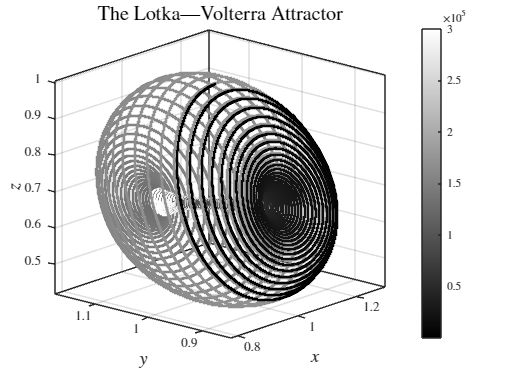

set(groot,"defaultAxesTickLabelInterpreter","latex")
set(groot,"defaultTextInterpreter","latex")
set(groot,"defaultLegendInterpreter","latex")
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

fig1 = figure();
scatter3(xsol_DVERK(:,1), xsol_DVERK(:,2), xsol_DVERK(:,3), 4,1:length(xsol_DVERK(:,1)),'filled');
colormap gray;
colorbar;
axis tight;
grid on;
box on;
view([-48.822 17.712])
xlabel('$x$','FontSize',14 );
ylabel('$y$','FontSize',14 );
zlabel('$z$','FontSize',14 );
title('The Lotka---Volterra Attractor','FontSize',16);

### The TSUCS2 Attractor

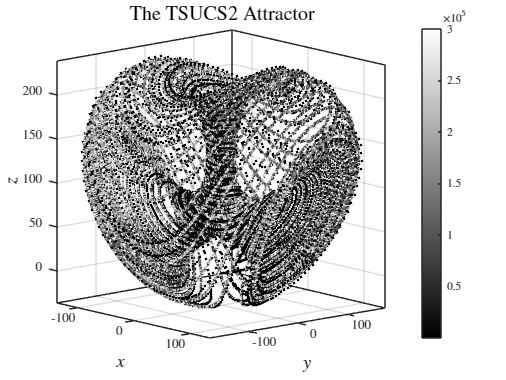

set(groot,"defaultAxesTickLabelInterpreter","latex")
set(groot,"defaultTextInterpreter","latex")
set(groot,"defaultLegendInterpreter","latex")
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

fig2 = figure();
scatter3(xsol_DP54(:,1), xsol_DP54(:,2), xsol_DP54(:,3), 4,1:length(xsol_DP54(:,1)),'filled');
colormap gray;
colorbar;
axis tight;
grid on;
box on;
view([49 11]);
xlabel('$x$','FontSize',14 );
ylabel('$y$','FontSize',14 );
zlabel('$z$','FontSize',14 );
title('The TSUCS2 Attractor','FontSize',16);

## **Block of exporting the obtained results**

exportgraphics(fig1, "images/The_Lotka_Volterra_Attractor.pdf", "ContentType","vector")

exportgraphics(fig1, "images/The_Lotka_Volterra_Attractor.png", "Resolution", 1200)

exportgraphics(fig2, "images/The_TSUCS2_Attractor.pdf", "ContentType","vector")

exportgraphics(fig2, "images/The_TSUCS2_Attractor.png", "Resolution", 1200)

save("results.mat")